## 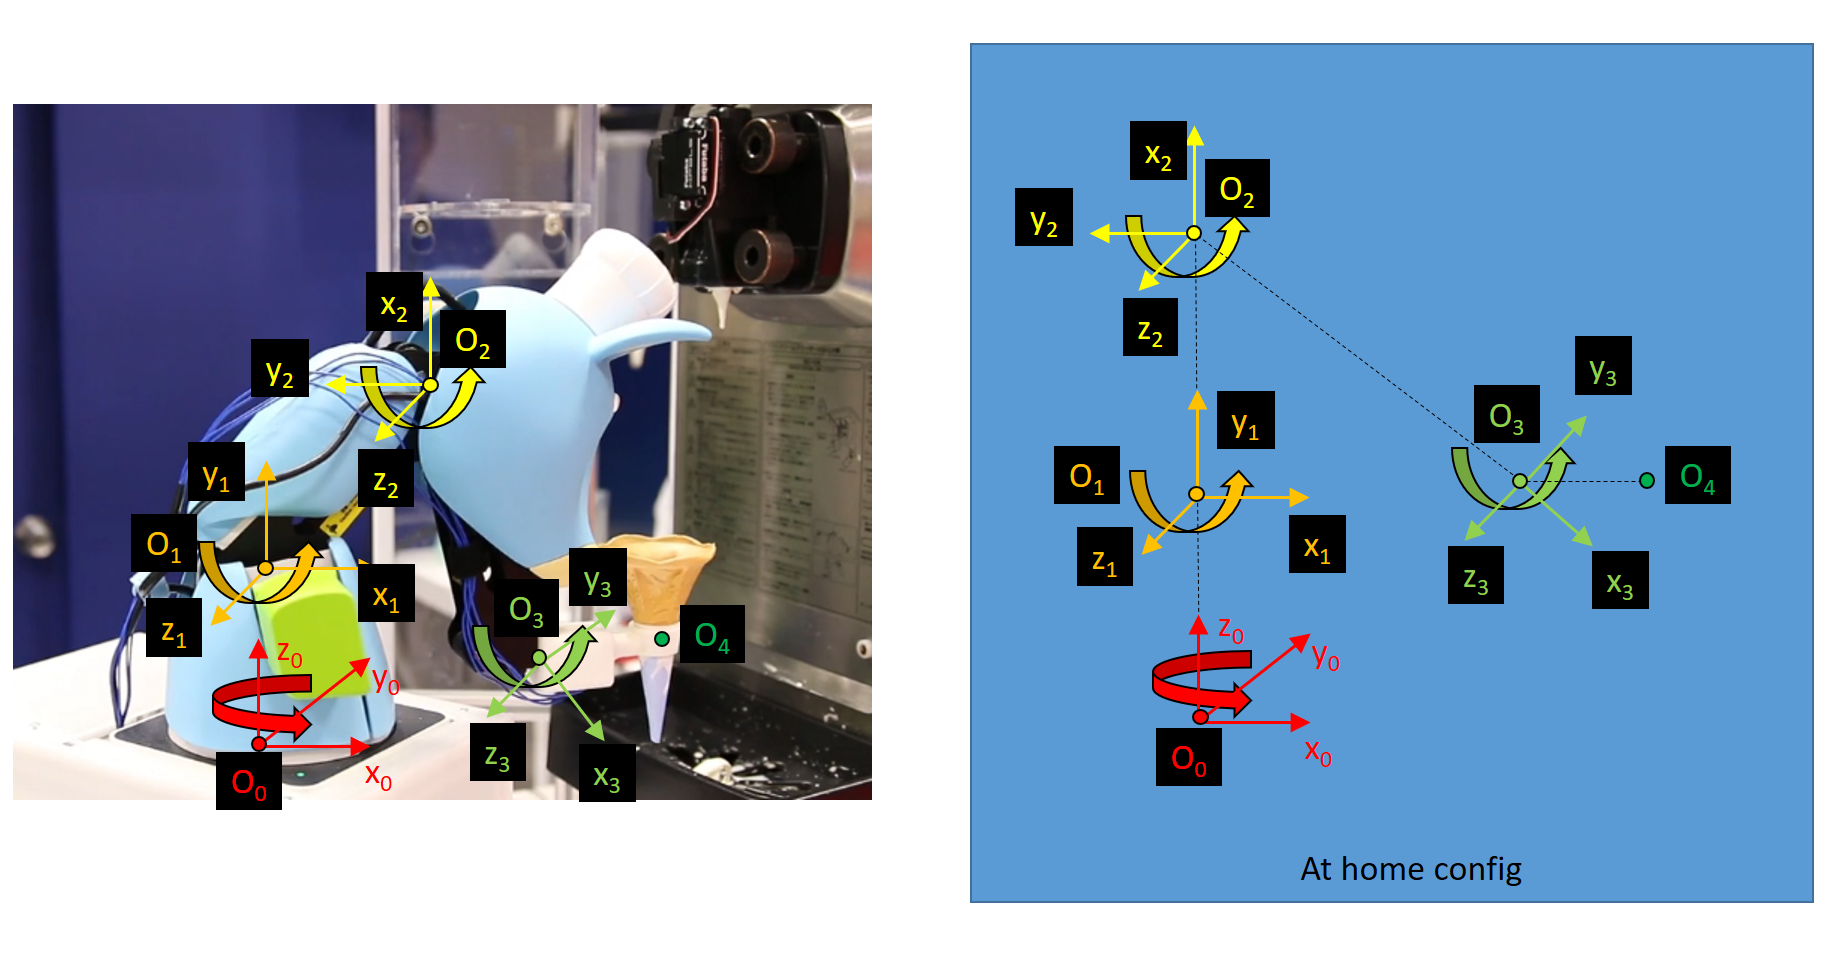

## Methods

From the DH table that we've generated for the robotic arm, we can generate the Jacobian for the arm. Once we have the Jacobian, we can determine both end effector velocities (linear and angular) as well as try to find if any singularities exist within the arm design.

The Jacobian of our arm will be a 6x3 matrix - 3 rows for each of the linear and angular velocities, and then a column for ecah joint on the robotic arm. Typically, the equations for the Jacobian of a given robotic joint are, for prismatic joints:


$$J=\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a prismatic joint*

...and for revolute joints, the Jacobian is found through:


$$J=\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_{i-1} 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a revolute joint*

Our arm is a four axis robot with each joint being a revolute joint. As such, the equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccc}
z_0 x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2 x\left(o_4 -o_2 \right) & z_3 x\left(o_4 -o_3 \right)\\
z_0  & z_1  & z_2  & z_3 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for our robot arm*

When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. We will be making use of the $\textrm{det}\left(J\right)=0$ to prove that we have found a singularity throughout this paper.

Once we have explored the Jacobian symbollically, we will use numerical computation methods to explore the singularities for the Mecademic arm. Most six axis robot arms have three common sources of singularities which the Mecademic arm shares. A **wrist singularity**, an **elbow singularity**, and an **overhead** **singularity** when the tool path crosses above the arm's head.

The **wrist singularity** occurs when a wrist joint has its base frame and secondary frame - in our case $\theta_3$ and $\theta_5$ are co-linear - when $\theta_5 ==0\;\textrm{or}\;\theta_5 ==\pi$.

The **elbow singularity** occurs when the elbow's orientation matches a value based on the geometry of the robot - specifically when the angle of the elbow matches the arctan of the elbow's distance between $\theta_3$ and $\theta_4$. Specifically, $\theta_3 =-\arctan \left(\frac{120}{38}\right)=-\arctan \left(\frac{60}{19}\right)\approx -72\ldotp 48\;\textrm{degrees}$.

The **overhead singularity** occurs when the robot arm moves the end effector over the z-axis plane, as through the $\theta_0$ and $\theta_1$ z-axis. If the tool passes overhead, effectively when $x==y==0$ for a given *x, y, z* for the coordinates of the tool, a singularity occurs.

## Results

We are going to represent our Jacobian first symbollically, and then perform numerical analysis on it to find singularities.

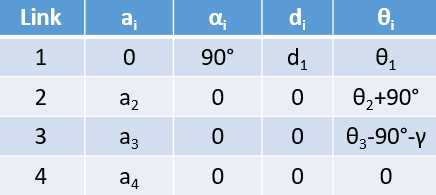delete me here for notes

syms theta1 theta2 theta3 d1 a2 a3 a4

dh_table = {
             [theta1                d1      0       0],
             [theta2+(pi/2)         0       a2      0],
             [theta3-(pi/2)         0       a3      0],
             [0                     0       a4      0],
           };

j = jacobian_from_dh_table(dh_table, true)

$$j = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\,\left(a_{3}+a_{4}\right) & -a_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2} & \sigma_{2} & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\,\left(a_{3}+a_{4}\right) & a_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)-a_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

Talk about the analytical jacobian


$$\begin{array}{l}
\left(\begin{array}{cccc}
\sigma_1  & \sigma_1  & -\mathrm{sin}\left(\theta_1 +\theta_2 +\theta_3 \right)\,{\left(a_3 +a_4 \right)} & -a_4 \,\mathrm{sin}\left(\theta_1 +\theta_2 +\theta_3 \right)\\
\sigma_2  & \sigma_2  & \mathrm{cos}\left(\theta_1 +\theta_2 +\theta_3 \right)\,{\left(a_3 +a_4 \right)} & a_4 \,\mathrm{cos}\left(\theta_1 +\theta_2 +\theta_3 \right)\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 1 & 1
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =-a_2 \,\mathrm{cos}\left(\theta_1 +\theta_2 \right)-a_3 \,\mathrm{sin}\left(\theta_1 +\theta_2 +\theta_3 \right)-a_4 \,\mathrm{sin}\left(\theta_1 +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =a_3 \,\mathrm{cos}\left(\theta_1 +\theta_2 +\theta_3 \right)-a_2 \,\mathrm{sin}\left(\theta_1 +\theta_2 \right)+a_4 \,\mathrm{cos}\left(\theta_1 +\theta_2 +\theta_3 \right)
\end{array}$$


Calculate the numerical Jacobian to find singularities:

thetas = 0:359

thetas =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


distances = zeros(1, length(thetas));
determinants = zeros(1, length(thetas));
for step = 1:length(thetas)
    theta = thetas(step);
    dh_table = {
             [thetas(step)          d1      0       0],
             [theta2+90             0       a2      0],
             [theta3-90             0       a3      0],
             [0                     0       a4      0],
           };
    determinants(step) = det(jacobian_from_dh_table(dh_table));
end

Unrecognized function or variable 'theta4'.


figure
title("Singularity for Elbow")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;
plot(thetas, determinants, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
yline(0);
xline(72.43);
hold off;

### Functions

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end